# Problemas - Tema 2

## METODOS DIRECTOS DE RESOLUCION DE SISTEMAS LINEALES

### Problema 15

Tenemos la expresión del voltaje como $v''(x) = r g v(x) , x \in [0, L]$. Además, $v(L) = v_L$ y $v'(0) = 0$. Luego, como sabemos que$r = 2, g = 0.5, L = 2 \text{ y } v_L = 1$, podemos escribir el problema que solucionaremos.


$$v''(x) = v(x), x \in [0, 2]$$



$$v(2) = 1, v'(0) = 0$$


#### (a)

Para obtener un sistema de 200 incognitas con 200 ecuaciones, realizaremos una partición con $h = \frac{2}{200}$ tal que $x_0 = 0$ y $x_{200} = 2$ y nuestro vector solución es tal que $[v0, v_1 ,\dots, v_{199}]^T$ con $v_k = v(x_k)$.

Luego, de nuestras condiciones iniciales debemos sacar la siguiente información.


$$v(2) = 1 \Rightarrow v_{200} = 1$$


y utilizando la diferencia finita central, 


$$v'(0) = 0 \Rightarrow \frac{v(h) - v(-h)}{2h} = 0 \Rightarrow \frac{v_1 - v_{-1}}{2h} = 0 \Rightarrow v_1 = v_{-1}$$


Ahora, desarrollamos la segunda derivada por la diferencia finita central.


$$v''(x) = v(x) \Rightarrow$$



$$\Rightarrow \frac{v(x + h) - 2 v(x) + v(x - h)}{h^2} = v(x)$$



$$\Leftrightarrow \frac{v(x + h) - (2 + h^2) v(x) + v(x - h)}{h^2} = 0$$



$$\Leftrightarrow v(x + h) - (2 + h^2) v(x) + v(x - h) = 0$$


Aplicando a diferentes valores de $x$ tal que $v_k = v(x_k), k \in \mathbb{N}$.

- Para $x_0$:    $v_1 - (2 + h^2) v_0 + v_{-1} = 0 \stackrel{v_1 = v_{-1}}{\Longrightarrow} 2 v_1 - (2 + h^2) v_0 = 0$

- Para $x_1$:    $v_2 - (2 + h^2) v_1 + v_0 = 0$

- 
$$\vdots$$


- Para $x_{199}$:  $v_{200} - (2 + h^2) v _ {199} + v_{198} = 0 \stackrel{v_{200} = 1}{\Longrightarrow} -(2 + h^2) v_{199} + v_{198} = -1$

Así, queda el sistema:


$$\pmatrix{ -(2 + h^2) & 2 & 0 & \cdots & \cdots & \cdots \cr 1 & -(2 + h^2) & 1 & \cdots & \cdots & \cdots \cr 0 & \ddots & \ddots & \ddots & 0 & 0 \cr 0 &0 & \ddots & \ddots & \ddots & 0 \cr \cdots & \cdots & \cdots & 1 & -(2 + h^2) & 1 \cr \cdots & \cdots & \cdots & 0 & 1 & -(2 + h^2) } \pmatrix{v_0 \cr v_1 \cr  \vdots \cr \vdots \cr v_{198} \cr v_{199}}  = \pmatrix{0 \cr  0 \cr \vdots \cr \vdots \cr  0 \cr-1 }$$


#### (b)

A continuación, utilizaremos todos los métodos directos para resolver el sistema. (Es importante haber ejecutado el script EjecutarEste para que esten cargados en el espacio de trabajo). Definimos el sistema y la funcion solución:

h = 2 / 200;
xk = linspace(0, 1.99, 200); xk = xk(:);
b = zeros(200, 1); b(200) = -1;
% Definimos por diagonales
mDiag = ones(200, 1) * -(2 + h^2);
lDiag = ones(199, 1);
uDiag = ones(199, 1); uDiag(1) = 2;

A = diag(mDiag) + diag(uDiag, 1) + diag(lDiag, -1);

f = @(x) 0.133 * exp(x) + 0.133 * exp(-x);
yk = feval(f, xk);

Resolvemos con todos los métodos y representamos junto a la función. Calculamos también el tiempo de ejecución y el error.

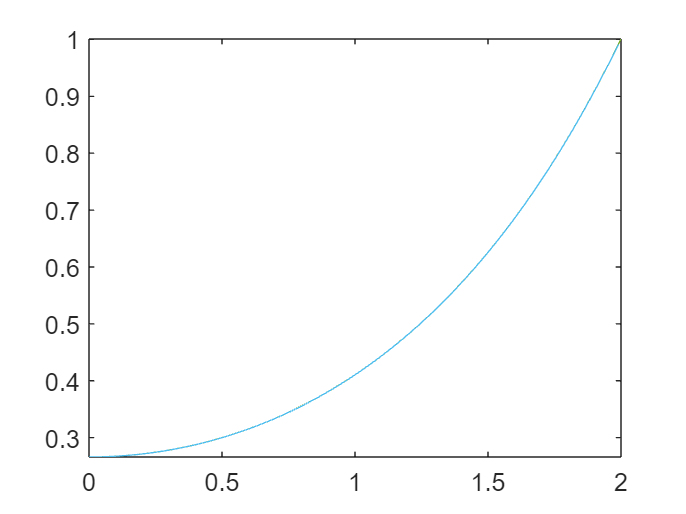

hold off

% CROUT
disp("CROUT");

CROUT


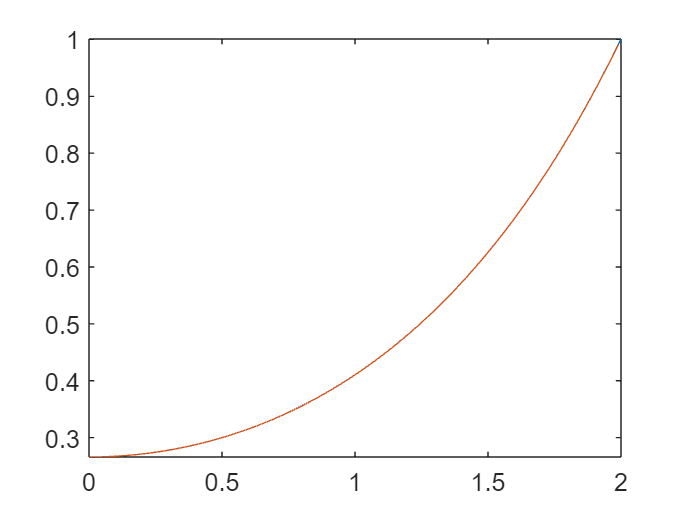

tic;
sol = ResolucionDirectaCrout(mDiag, lDiag, uDiag, b);
time = toc;
error = sum(abs(yk - sol));
fplot(f, [0, 2]);
hold on
plot(xk, yk);

disp("El error es de " + error);

El error es de 0.071112


disp("Ha tardado " + time);

Ha tardado 0.0023195


hold off

% CHOLESKY
disp("CHOLESKY");

CHOLESKY


tic;
sol = ResolucionDirectaCholesky(A, b);
time = toc;
error = sum(abs(yk - sol));
fplot(f, [0, 2]);
hold on
plot(xk, yk);

disp("El error es de " + error);

El error es de 95.815


disp("Ha tardado " + time);

Ha tardado 0.045729


Vemos que el error para el método de Cholesky es muy grande. Esto se debe a que la matriz no es definida positiva

DefinidaPositiva(A);

NO DEFINIDA POSITIVA.


hold off

% FACTORIZACION CROUT
disp("FCATORIZACION CROUT");

FCATORIZACION CROUT


tic;
sol = ResolucionDirectaFactCrout(A, b);
time = toc;
error = sum(abs(yk - sol));
fplot(f, [0, 2]);
hold on
plot(xk, yk);

disp("El error es de " + error);

El error es de 20.2385


disp("Ha tardado " + time);

Ha tardado 0.17585


El error es de nuevo enorme, esto se debe a que la matriz no es simetrica.

hold off 

% HOUSEHOLDER
disp("HOUSEHOLDER");

HOUSEHOLDER


tic;
sol = ResolucionDirectaHouseholder(A, b);
time = toc;
error = sum(abs(yk - sol));
fplot(f, [0, 2]);
hold on
plot(xk, yk);

disp("El error es de " + error);

El error es de 0.071112


disp("Ha tardado " + time);

Ha tardado 0.11403


### Problema 16

...